%Generate equations of motion for a rocking semicircle, in terms of
%velocity. 

clear all
syms vx(t) vy(t) theta(t) m r g Ff(t) N(t)

%Set up equations for a rolling semi-circle. Notice that the roll
%conditions are given in terms of a derivative.  This will have an impact
%in a second. 


Izz = m*r^2*(1/4 - 16/9/pi^2) + m*r^2/4;
R_b_I = [cos(theta(t)) -sin(theta(t)) 0;sin(theta(t)) cos(theta(t)) 0;0 0 1];

vG=[vx(t);vy(t)];
F=[Ff(t);N(t)];

% Newton's 2nd
eq1=m*diff(vG,t)==F-m*g*[0;1];

% Euler's 2nd
r_CP_G = [0;-r;0] + R_b_I*[0;4*r/3/pi;0];
MG=cross(r_CP_G,[F;0]);
eq2=Izz*diff(theta(t),t,t)==MG(3);

% roll without slip
vGr = cross([0;0;diff(theta(t),t)],-r_CP_G);
eq3 = vG == vGr(1:2);

DES=[eq1;eq2];
disp_const=[];
vel_const=[eq3];

[governingODEs,PPs]=generateGoveringDEs([DES],[],vel_const,[theta,diff(theta)])

The unknown functions are:
Ff(force)
N(force)
theta
vx
vy

Expected Number of State Variables:2


$$governingODEs = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=-\frac{432345564227567616\,\pi \,\left(r\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+g\,\sin\left(\theta \left(t\right)\right)\right)}{r\,\left(576460752303423488\,{\cos\left(\theta \left(t\right)\right)}^{2}-864691128455135232\,\pi \,\cos\left(\theta \left(t\right)\right)+576460752303423488\,{\sin\left(\theta \left(t\right)\right)}^{2}+427981074009278211\,\pi^{2}\right)}$$

The unknown functions (just the base functions, not derivatives) are: theta(t)


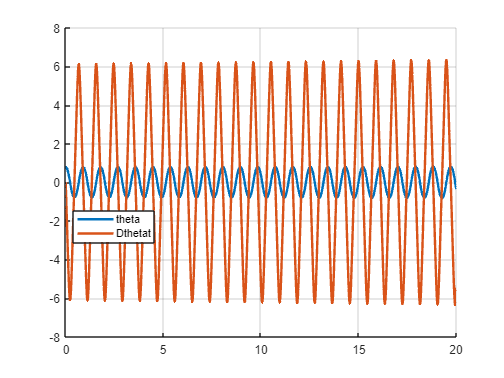



paramVals.m=1; paramVals.r=0.1; paramVals.g=9.81;

soln=timeStepODESystem(subs(governingODEs,paramVals),[0,20],[theta==pi/4,diff(theta)==0],subs(PPs,paramVals));